% 定点化 FxLMS 仿真（FPGA 验证）- 增强版
clear; clc; close all;

%% 参数设置
fs = 10000;                 % 采样率 [Hz]
dt = 1/fs;
duration = 10;              % 仿真时长 [s]
n_samples = duration * fs;
t = (0:n_samples-1)' * dt;

vib_freq = 100;
vib_amp = 5.0;

L = 128;                    % 滤波器阶数
mu_fixed = 5e-6;            % 固定步长
delay = 4;                  % 次级路径延迟步数
s_hat_gain = -0.2;          % 次级路径增益
s_hat = zeros(delay+1, 1);
s_hat(end) = s_hat_gain;

% 预先生成振动信号（避免循环内重复调用）
vib_source = VibrationSource();
vib_source.frequencies = vib_freq;
vib_source.amplitudes = vib_amp;
vib_source.phases = 0;
vib_source.noise_level = 0.05;
vibration_pre = zeros(n_samples,1);
fprintf('生成振动信号...\n');

生成振动信号...


for k = 1:n_samples
    condition = struct('spindle_rpm', 3000, 'enable_noise', true, ...
        'enable_frequency_modulation', false, ...
        'enable_amplitude_modulation', false, ...
        'enable_random_shock', false);
    vibration_pre(k) = generate_vibration(vib_source, t(k), condition);
end

%% 1. 浮点模型（基准）
fprintf('运行浮点基准模型...\n');

运行浮点基准模型...


[err_float, y_float] = fxlms_float(vibration_pre, dt, L, mu_fixed, s_hat);

负载 5.0 N: 目标平均阻尼比 = 0.0250
  各模态阻尼比: [0.0150, 0.0225, 0.0375]
作动器状态已重置
..........


rms_float = rms(err_float);
total_reduction_float = 10*log10(rms(vibration_pre)^2 / rms_float^2);
fprintf('浮点抑制比: %.2f dB\n', total_reduction_float);

浮点抑制比: 22.83 dB



%% 2. 定点模型（手动量化，调整位宽）
fprintf('运行定点模型...\n');

运行定点模型...


% 定义定点格式（扩大整数位，防止溢出）
% 数据：16位有符号，4位整数，12位小数（范围 -8~7.999，可覆盖 ±5）
DATA_INT_BITS = 4;
DATA_FRAC_BITS = 12;
% 系数：24位有符号，10位整数，14位小数（范围 -512~511，足够大）
COEFF_INT_BITS = 16; %原10
COEFF_FRAC_BITS = 24;   % 最小变化量 ~ 6e-8 原14
% 步长：32位有符号，2位整数，30位小数
MU_INT_BITS = 2;
MU_FRAC_BITS = 30;

% 量化函数
quant_data = @(x) round(x * 2^DATA_FRAC_BITS) / 2^DATA_FRAC_BITS;
quant_coeff = @(x) round(x * 2^COEFF_FRAC_BITS) / 2^COEFF_FRAC_BITS;
quant_mu = @(x) round(x * 2^MU_FRAC_BITS) / 2^MU_FRAC_BITS;

% 量化常数
s_hat_q = quant_coeff(s_hat);
mu_q = quant_mu(mu_fixed);

% 初始化
w_q = zeros(L,1);
x_buffer_q = zeros(L,1);
xf_buffer_q = zeros(L,1);
err_q = zeros(n_samples,1);

% 物理模型
structure = StructuralDynamics(fs, 5, false);

负载 5.0 N: 目标平均阻尼比 = 0.0250
  各模态阻尼比: [0.0150, 0.0225, 0.0375]


actuator = PiezoActuator();

作动器状态已重置



acc_control = 0;  % 控制产生的加速度（浮点，最后量化）

for k = 1:n_samples
    % 振动（量化）
    vib_q = quant_data(vibration_pre(k));
    err = vib_q + acc_control;
    err_q(k) = err;
    
    if k >= L
        % 更新 x_buffer
        x_buffer_q = [vib_q; x_buffer_q(1:end-1)];
        
        % 计算滤波参考信号 xf
        xf = 0;
        M = length(s_hat_q);
        for j = 1:min(M, k)
            xf = xf + s_hat_q(j) * x_buffer_q(j);
        end
        xf_buffer_q = [xf; xf_buffer_q(1:end-1)];
        
        % 控制输出 y = w * x_buffer
        y = 0;
        for j = 1:L
            y = y + w_q(j) * x_buffer_q(j);
        end
        y = quant_data(y);
        
        % 系数更新（量化）
        for j = 1:L
            w_q(j) = w_q(j) - mu_q * err * xf_buffer_q(j);
            w_q(j) = quant_coeff(w_q(j));
        end
    else
        y = 0;
    end
    
    % 限幅
    y = max(min(y, 10), -10);
    
    % 执行控制（物理模型用浮点）
    [~, force] = actuator.actuate(y, dt);
    [~, ~] = structure.respond(force, dt);
    acc_control = structure.get_acceleration(2);
    
    % 在定点模型循环中，每 1000 步打印一次
if mod(k, 1000) == 0 && k >= L
    fprintf('k=%d, mu_q=%.10f, norm(w)=%.3e, max|xf|=%.3e\n', ...
        k, mu_q, norm(w_q), max(abs(xf_buffer_q)));
end


    % 进度显示
    if mod(k, floor(n_samples/10)) == 0
        fprintf('.');
    end
end

k=1000, mu_q=0.0000050003, norm(w)=4.181e-02, max|xf|=1.010e+00
k=2000, mu_q=0.0000050003, norm(w)=5.174e-02, max|xf|=1.014e+00
k=3000, mu_q=0.0000050003, norm(w)=5.288e-02, max|xf|=1.013e+00
k=4000, mu_q=0.0000050003, norm(w)=5.298e-02, max|xf|=1.015e+00
k=5000, mu_q=0.0000050003, norm(w)=5.312e-02, max|xf|=1.011e+00
k=6000, mu_q=0.0000050003, norm(w)=5.318e-02, max|xf|=1.015e+00
k=7000, mu_q=0.0000050003, norm(w)=5.316e-02, max|xf|=1.011e+00
k=8000, mu_q=0.0000050003, norm(w)=5.312e-02, max|xf|=1.015e+00
k=9000, mu_q=0.0000050003, norm(w)=5.303e-02, max|xf|=1.007e+00
k=10000, mu_q=0.0000050003, norm(w)=5.299e-02, max|xf|=1.013e+00


.

k=11000, mu_q=0.0000050003, norm(w)=5.304e-02, max|xf|=1.017e+00
k=12000, mu_q=0.0000050003, norm(w)=5.311e-02, max|xf|=1.012e+00
k=13000, mu_q=0.0000050003, norm(w)=5.312e-02, max|xf|=1.013e+00
k=14000, mu_q=0.0000050003, norm(w)=5.309e-02, max|xf|=1.010e+00
k=15000, mu_q=0.0000050003, norm(w)=5.304e-02, max|xf|=1.015e+00
k=16000, mu_q=0.0000050003, norm(w)=5.304e-02, max|xf|=1.019e+00
k=17000, mu_q=0.0000050003, norm(w)=5.305e-02, max|xf|=1.009e+00
k=18000, mu_q=0.0000050003, norm(w)=5.315e-02, max|xf|=1.013e+00
k=19000, mu_q=0.0000050003, norm(w)=5.318e-02, max|xf|=1.025e+00
k=20000, mu_q=0.0000050003, norm(w)=5.312e-02, max|xf|=1.017e+00


.

k=21000, mu_q=0.0000050003, norm(w)=5.308e-02, max|xf|=1.017e+00
k=22000, mu_q=0.0000050003, norm(w)=5.307e-02, max|xf|=1.015e+00
k=23000, mu_q=0.0000050003, norm(w)=5.310e-02, max|xf|=1.018e+00
k=24000, mu_q=0.0000050003, norm(w)=5.310e-02, max|xf|=1.007e+00
k=25000, mu_q=0.0000050003, norm(w)=5.313e-02, max|xf|=1.008e+00
k=26000, mu_q=0.0000050003, norm(w)=5.306e-02, max|xf|=1.018e+00
k=27000, mu_q=0.0000050003, norm(w)=5.300e-02, max|xf|=1.018e+00
k=28000, mu_q=0.0000050003, norm(w)=5.303e-02, max|xf|=1.010e+00
k=29000, mu_q=0.0000050003, norm(w)=5.307e-02, max|xf|=1.006e+00
k=30000, mu_q=0.0000050003, norm(w)=5.310e-02, max|xf|=1.011e+00


.

k=31000, mu_q=0.0000050003, norm(w)=5.313e-02, max|xf|=1.009e+00
k=32000, mu_q=0.0000050003, norm(w)=5.311e-02, max|xf|=1.012e+00
k=33000, mu_q=0.0000050003, norm(w)=5.305e-02, max|xf|=1.007e+00
k=34000, mu_q=0.0000050003, norm(w)=5.302e-02, max|xf|=1.003e+00
k=35000, mu_q=0.0000050003, norm(w)=5.305e-02, max|xf|=1.012e+00
k=36000, mu_q=0.0000050003, norm(w)=5.307e-02, max|xf|=1.011e+00
k=37000, mu_q=0.0000050003, norm(w)=5.310e-02, max|xf|=1.022e+00
k=38000, mu_q=0.0000050003, norm(w)=5.312e-02, max|xf|=1.011e+00
k=39000, mu_q=0.0000050003, norm(w)=5.311e-02, max|xf|=1.025e+00
k=40000, mu_q=0.0000050003, norm(w)=5.313e-02, max|xf|=1.012e+00


.

k=41000, mu_q=0.0000050003, norm(w)=5.309e-02, max|xf|=1.015e+00
k=42000, mu_q=0.0000050003, norm(w)=5.306e-02, max|xf|=1.012e+00
k=43000, mu_q=0.0000050003, norm(w)=5.307e-02, max|xf|=1.012e+00
k=44000, mu_q=0.0000050003, norm(w)=5.312e-02, max|xf|=1.006e+00
k=45000, mu_q=0.0000050003, norm(w)=5.308e-02, max|xf|=1.015e+00
k=46000, mu_q=0.0000050003, norm(w)=5.308e-02, max|xf|=1.023e+00
k=47000, mu_q=0.0000050003, norm(w)=5.308e-02, max|xf|=1.007e+00
k=48000, mu_q=0.0000050003, norm(w)=5.311e-02, max|xf|=1.024e+00
k=49000, mu_q=0.0000050003, norm(w)=5.311e-02, max|xf|=1.015e+00
k=50000, mu_q=0.0000050003, norm(w)=5.303e-02, max|xf|=1.018e+00


.

k=51000, mu_q=0.0000050003, norm(w)=5.302e-02, max|xf|=1.015e+00
k=52000, mu_q=0.0000050003, norm(w)=5.305e-02, max|xf|=1.019e+00
k=53000, mu_q=0.0000050003, norm(w)=5.307e-02, max|xf|=1.010e+00
k=54000, mu_q=0.0000050003, norm(w)=5.309e-02, max|xf|=1.005e+00
k=55000, mu_q=0.0000050003, norm(w)=5.316e-02, max|xf|=1.015e+00
k=56000, mu_q=0.0000050003, norm(w)=5.318e-02, max|xf|=1.019e+00
k=57000, mu_q=0.0000050003, norm(w)=5.311e-02, max|xf|=1.010e+00
k=58000, mu_q=0.0000050003, norm(w)=5.304e-02, max|xf|=1.013e+00
k=59000, mu_q=0.0000050003, norm(w)=5.303e-02, max|xf|=1.012e+00
k=60000, mu_q=0.0000050003, norm(w)=5.302e-02, max|xf|=1.019e+00


.

k=61000, mu_q=0.0000050003, norm(w)=5.311e-02, max|xf|=1.013e+00
k=62000, mu_q=0.0000050003, norm(w)=5.316e-02, max|xf|=1.005e+00
k=63000, mu_q=0.0000050003, norm(w)=5.314e-02, max|xf|=1.007e+00
k=64000, mu_q=0.0000050003, norm(w)=5.310e-02, max|xf|=1.013e+00
k=65000, mu_q=0.0000050003, norm(w)=5.300e-02, max|xf|=1.014e+00
k=66000, mu_q=0.0000050003, norm(w)=5.300e-02, max|xf|=1.012e+00
k=67000, mu_q=0.0000050003, norm(w)=5.311e-02, max|xf|=1.018e+00
k=68000, mu_q=0.0000050003, norm(w)=5.310e-02, max|xf|=1.016e+00
k=69000, mu_q=0.0000050003, norm(w)=5.312e-02, max|xf|=1.024e+00
k=70000, mu_q=0.0000050003, norm(w)=5.311e-02, max|xf|=1.010e+00


.

k=71000, mu_q=0.0000050003, norm(w)=5.308e-02, max|xf|=1.012e+00
k=72000, mu_q=0.0000050003, norm(w)=5.306e-02, max|xf|=1.018e+00
k=73000, mu_q=0.0000050003, norm(w)=5.304e-02, max|xf|=1.019e+00
k=74000, mu_q=0.0000050003, norm(w)=5.307e-02, max|xf|=1.023e+00
k=75000, mu_q=0.0000050003, norm(w)=5.314e-02, max|xf|=1.009e+00
k=76000, mu_q=0.0000050003, norm(w)=5.315e-02, max|xf|=1.012e+00
k=77000, mu_q=0.0000050003, norm(w)=5.311e-02, max|xf|=1.015e+00
k=78000, mu_q=0.0000050003, norm(w)=5.305e-02, max|xf|=1.023e+00
k=79000, mu_q=0.0000050003, norm(w)=5.296e-02, max|xf|=1.017e+00
k=80000, mu_q=0.0000050003, norm(w)=5.302e-02, max|xf|=1.011e+00


.

k=81000, mu_q=0.0000050003, norm(w)=5.309e-02, max|xf|=1.015e+00
k=82000, mu_q=0.0000050003, norm(w)=5.317e-02, max|xf|=1.006e+00
k=83000, mu_q=0.0000050003, norm(w)=5.312e-02, max|xf|=1.000e+00
k=84000, mu_q=0.0000050003, norm(w)=5.310e-02, max|xf|=1.009e+00
k=85000, mu_q=0.0000050003, norm(w)=5.304e-02, max|xf|=1.016e+00
k=86000, mu_q=0.0000050003, norm(w)=5.308e-02, max|xf|=1.030e+00
k=87000, mu_q=0.0000050003, norm(w)=5.311e-02, max|xf|=1.018e+00
k=88000, mu_q=0.0000050003, norm(w)=5.314e-02, max|xf|=1.028e+00
k=89000, mu_q=0.0000050003, norm(w)=5.310e-02, max|xf|=1.020e+00
k=90000, mu_q=0.0000050003, norm(w)=5.302e-02, max|xf|=1.012e+00


.

k=91000, mu_q=0.0000050003, norm(w)=5.308e-02, max|xf|=1.014e+00
k=92000, mu_q=0.0000050003, norm(w)=5.310e-02, max|xf|=1.018e+00
k=93000, mu_q=0.0000050003, norm(w)=5.315e-02, max|xf|=1.021e+00
k=94000, mu_q=0.0000050003, norm(w)=5.314e-02, max|xf|=1.016e+00
k=95000, mu_q=0.0000050003, norm(w)=5.306e-02, max|xf|=1.017e+00
k=96000, mu_q=0.0000050003, norm(w)=5.300e-02, max|xf|=1.009e+00
k=97000, mu_q=0.0000050003, norm(w)=5.299e-02, max|xf|=1.007e+00
k=98000, mu_q=0.0000050003, norm(w)=5.310e-02, max|xf|=1.011e+00
k=99000, mu_q=0.0000050003, norm(w)=5.317e-02, max|xf|=1.004e+00
k=100000, mu_q=0.0000050003, norm(w)=5.318e-02, max|xf|=1.011e+00


.

fprintf(' 完成\n');

 完成



rms_q = rms(err_q);
total_reduction_q = 10*log10(rms(vibration_pre)^2 / rms_q^2);
fprintf('定点抑制比: %.2f dB\n', total_reduction_q);

定点抑制比: 22.83 dB


fprintf('性能差异: %.2f dB\n', total_reduction_float - total_reduction_q);

性能差异: -0.00 dB


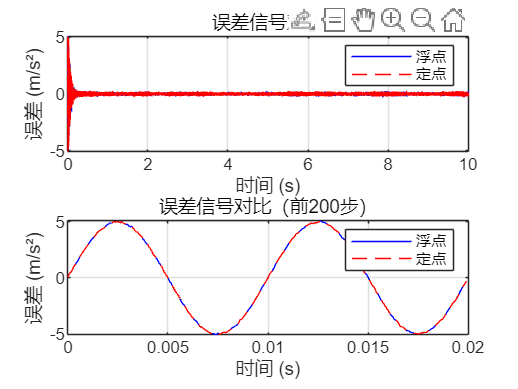


%% 绘图对比
figure;
subplot(2,1,1);
plot(t, err_float, 'b', t, err_q, 'r--');
xlabel('时间 (s)'); ylabel('误差 (m/s²)');
legend('浮点', '定点');
title('误差信号对比');
grid on;

subplot(2,1,2);
plot(t(1:200), err_float(1:200), 'b', t(1:200), err_q(1:200), 'r--');
xlabel('时间 (s)'); ylabel('误差 (m/s²)');
legend('浮点', '定点');
title('误差信号对比（前200步）');
grid on;


%% 辅助函数：浮点 FxLMS
function [error, y_linear] = fxlms_float(vibration, dt, L, mu_fixed, s_hat)
    n_samples = length(vibration);
    structure = StructuralDynamics(1/dt, 5, false);
    actuator = PiezoActuator();
    
    w = zeros(L,1);
    x_buffer = zeros(max(L, length(s_hat)),1);
    xf_buffer = zeros(L,1);
    
    error = zeros(n_samples,1);
    y_linear = zeros(n_samples,1);
    acc_control = 0;
    
    for k = 1:n_samples
        err = vibration(k) + acc_control;
        error(k) = err;
        
        if k >= L
            x_buffer = [vibration(k); x_buffer(1:end-1)];
            xf = 0;
            M = length(s_hat);
            for j = 1:min(M, k)
                xf = xf + s_hat(j) * x_buffer(j);
            end
            xf_buffer = [xf; xf_buffer(1:end-1)];
            y = w' * x_buffer(1:L);
            y_linear(k) = y;
            w = w - mu_fixed * err * xf_buffer;
        else
            y = 0;
        end
        
        y = max(min(y, 10), -10);
        
        [~, force] = actuator.actuate(y, dt);
        [~, ~] = structure.respond(force, dt);
        acc_control = structure.get_acceleration(2);
        
        if mod(k, floor(n_samples/10)) == 0
            fprintf('.');
        end
    end
    fprintf('\n');
end